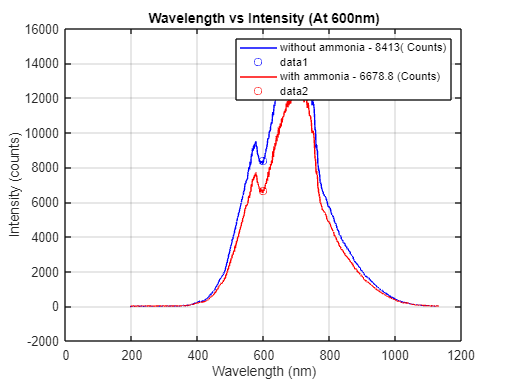

% Define the file names and corresponding labels
filenames = {


"C:\Users\jerub\Desktop\ECCE\Courses-Modules\Msc Project\lbl deposition\amonia sensing\1000ppm_HR4C58731_00001.txt"
"C:\Users\jerub\Desktop\ECCE\Courses-Modules\Msc Project\lbl deposition\amonia sensing\1000ppm_HR4C58731_00150.txt"
    };

labels = {
   'without ammonia - 8413( Counts)',
   'with ammonia - 6678.8 (Counts)'
};

% Initialize a figure
figure;

% Initialize a table to store intensity values at 650 nm
intensityTable = table('Size', [length(filenames), 2], 'VariableTypes', {'string', 'double'}, ...
                       'VariableNames', {'File', 'Intensity_at_650nm'});

% Loop through each file and plot the data
colors = {'b-', 'r-', 'g-', 'm-', 'c-', 'k-', 'y-', 'b--'}; % Define colors for each plot
for i = 1:length(filenames)
    % Read the data from the current file
    data = readmatrix(filenames{i});
    wavelength = data(:, 1);
    intensity = data(:, 2);
    
    % Apply Savitzky-Golay filter for smoothing
    smoothed_intensity = sgolayfilt(intensity, 3, 11); % Use polynomial order 3 and frame size 11
    
    % Plot the smoothed data on the same graph
    plot(wavelength, smoothed_intensity, colors{i}, 'DisplayName', labels{i});
    hold on;
    
    % Find and mark the intensity at 650 nm
    [~, idx] = min(abs(wavelength - 600));
    intensity_at_650nm = smoothed_intensity(idx);
    plot(wavelength(idx), intensity_at_650nm, 'o', 'Color', colors{i}(1)); % Mark with same color
    
    % Store the intensity at 650 nm in the table
    intensityTable.File(i) = labels{i};
    intensityTable.Intensity_at_650nm(i) = intensity_at_650nm;
end

% Label the axes and the graph
xlabel('Wavelength (nm)');
ylabel('Intensity (counts)');
title('Wavelength vs Intensity (At 600nm)');
legend('show'); % Show the legend
grid on;
hold off;


% Display the intensity table
disp(intensityTable);

                  File                   Intensity_at_650nm
    _________________________________    __________________

    "without ammonia - 8413( Counts)"          8398.7      
    "with ammonia - 6678.8 (Counts)"           6687.6      

